## Aproximación de pi

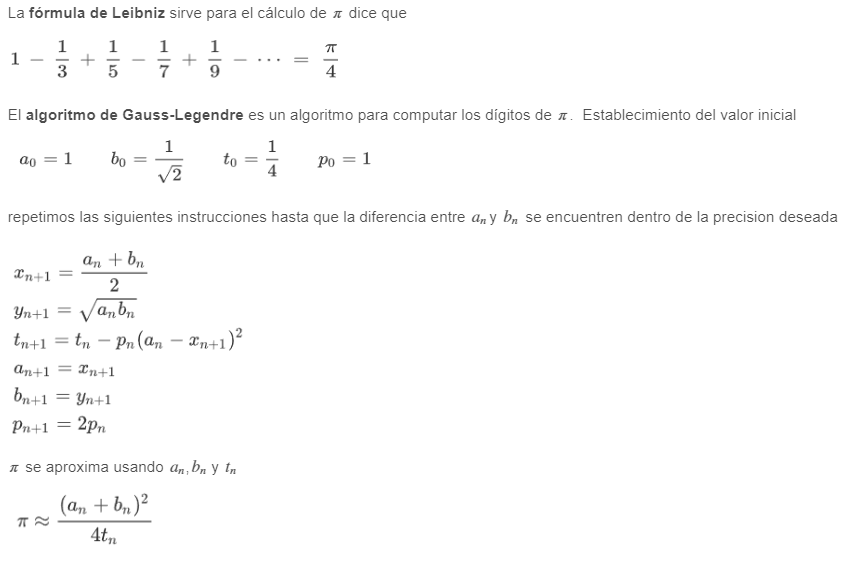

format long;

pi_leib = leibniz_pi(10)

pi_leib =    3.041839618929403


pi_gl = gauss_legendre_pi(10)

pi_gl =    3.141592653589794


error_leib = abs(pi - pi_leib)/pi

error_leib =    0.031752377109236


error_gl = abs(pi - pi_gl)/pi

error_gl =      2.827159716856459e-16


function pi_ap = leibniz_pi(n)
% n: número de iteraciones
% pi_ap: valor aproximado de pi
    pi_ap = 0;  
    
    for i = 0:n-1
        term = (-1)^i / (2*i + 1);  
        pi_ap = pi_ap + term; 
    end
    
    % complete aquí
    pi_ap = 4 * pi_ap; 
end

function pi_ap = gauss_legendre_pi(n)
% n: número de iteraciones
% pi_approx: valor aproximado de pi

    % complete aquí
    a = 1;
    b = 1 / sqrt(2);
    t = 1 / 4;
    p = 1;
    
    for i= 0:n-1
        x = (a + b) / 2;
        y = sqrt(a * b);
        t = t - p * ((a - x)^2);

        a = x;
        b = y;
        p = 2 * p;
    end
    
    pi_ap = ((a + b)^2 / (4 * t));
end